# Storm Events 2017 Analysis

## Background and Scope

### Import the Data

You may use an import function. If not using an import function, include the code used to import the data (it may be generated from the Import Tool)

events = importfile("StormEvents_2017_finalProject.csv")

events = 57005×24 table
    EpisodeID      Event_ID         State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                  

### Two States Most Impacted by Harvey

Clearly state the two states in order 

%Two States Most impacted by Harvey
data2 = events;
AugSepData = data2(ismember(data2.Month,{'August','September'}),:);
AugSepData.Property_Cost(ismissing(AugSepData.Property_Cost)) = 0;

HarveyData = AugSepData(AugSepData.Begin_Date_Time >= '2017-08-17 00:00:00'...
    & AugSepData.End_Date_Time <= '2017-09-03 23:59:00',:);

statePropertyCost = groupsummary(HarveyData,"State","sum","Property_Cost");
statePropertyCost = sortrows(statePropertyCost,'sum_Property_Cost','descend')

statePropertyCost = 57×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                272           7.7427e+10    
    LOUISIANA             85           7.5277e+07    
    NORTH CAROLINA        59           1.2339e+07    
    WASHINGTON             2                4e+06    
    FLORIDA               68            2.237e+06    
    MINNESOTA             24            1.375e+06    
    NEBRASKA              62            1.054e+06    
    MISSISSIPPI           39             9.15e+05    
    NEW YORK             109             6.41e+05    
    TENNESSEE             46             5.04e+05    
    PENNSYLVANIA         203           4.9163e+05    
    KENTUCKY              20             4.35e+05    
    CALIFORNIA            74             3.29e+05    
    IOWA                  54             3.21e+05    
  




% TEXAS , LOUISIANA (Top 2)

TopTwoStates = HarveyData(ismember(HarveyData.State,{'LOUISIANA','TEXAS'}),:);

Top two states impaced by Hurricane Harvey are:

- Texas 

- Louisiana

### Table of Events for Two Most Impacted States

Create and display a few rows of events that include only the two most affected states

EventsTopTwoStates = table(TopTwoStates.State, TopTwoStates.Event_Type);

% renaming variables
EventsTopTwoStates.Properties.VariableNames{'Var1'} = 'state';
EventsTopTwoStates.Properties.VariableNames{'Var2'} = 'event_Type';
EventsTopTwoStates

EventsTopTwoStates = 357×2 table
    state       event_Type    
    _____    _________________

    TEXAS    Tropical Storm   
    TEXAS    Tropical Storm   
    TEXAS    Tropical Storm   
    TEXAS    Tropical Storm   
    TEXAS    Tropical Storm   
    TEXAS    Tropical Storm   
    TEXAS    Flash Flood      
    TEXAS    Thunderstorm Wind
    TEXAS    Flash Flood      
    TEXAS    Flash Flood      
    TEXAS    Flash Flood      
    TEXAS    Flash Flood      
    TEXAS    Flash Flood      
    TEXAS    Thunderstorm Wind
    TEXAS    Thunderstorm Wind
    TEXAS    Thunderstorm Wind


## Visualizations

### Figure of Event Types

Create a figure showing the type and number of occurances for events related to Harvey in the two states

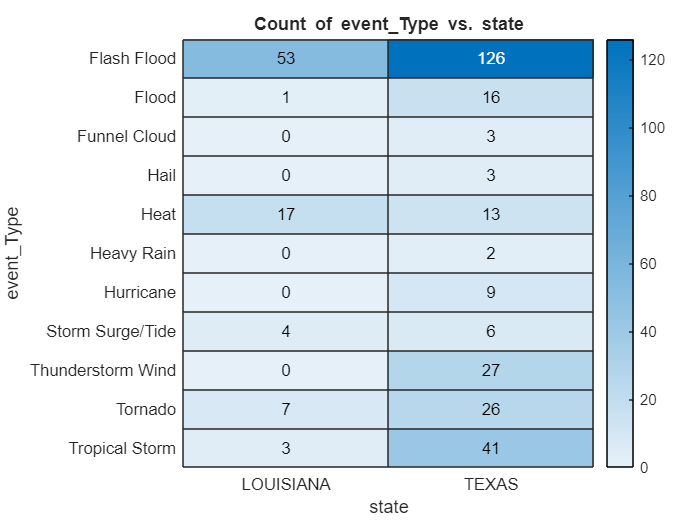

groupcounts(EventsTopTwoStates,"event_Type");

% This removes all categories with 0 occurrences from the state variable and event_type variable in the EventsTopTwo table.
EventsTopTwoStates.state = removecats(EventsTopTwoStates.state);
EventsTopTwoStates.event_Type = removecats(EventsTopTwoStates.event_Type);

heatmap(EventsTopTwoStates,"state","event_Type")

### Figure of Event Locations

Show the location of events in the two states. Be sure to use different markers for the two states

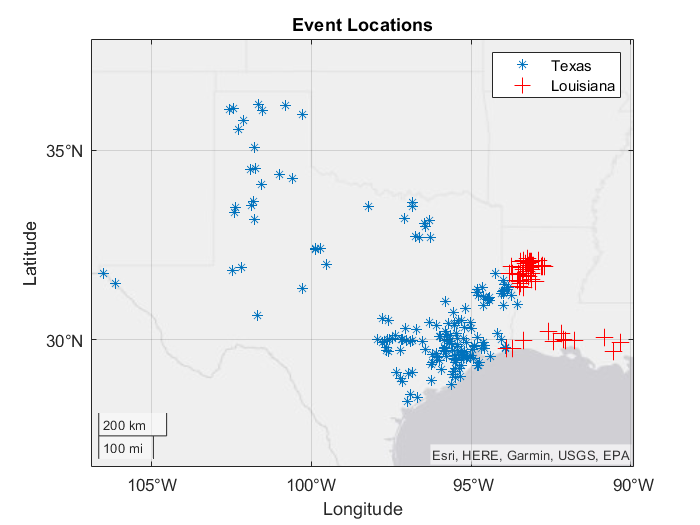

eventTexas = TopTwoStates(TopTwoStates.State=="TEXAS" , :);
eventLouisiana = TopTwoStates(TopTwoStates.State=="LOUISIANA", :);

geoplot(eventTexas.Begin_Lat,eventTexas.Begin_Lon,'*');
hold on
geoplot(eventLouisiana.Begin_Lat,eventLouisiana.Begin_Lon,...
    "Color","red","LineStyle","none","Marker","+","MarkerSize",10);
hold off
legend('Texas','Louisiana');

geolimits([26.5 37.8],[-106.9 -89.9]);
title('Event Locations');

## Analysis

### Three Counties with Most Events in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 1.

%mode(HarveyData.CZ_Name);
%heatmap(TopTwoStates, "CZ_Name","Event_Type")
TopTwoStates;

Texas = TopTwoStates(TopTwoStates.State == 'TEXAS',:);
%summary(Texas);

Texas.State = removecats(Texas.State);
Texas.CZ_Name = removecats(Texas.CZ_Name);

mode(Texas.CZ_Name);
county = groupsummary(Texas,"CZ_Name");

county = sortrows(county,'GroupCount','descend')

county = 95×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            21    
    GALVESTON         17    
    FORT BEND         13    
    ANGELINA          12    
    BRAZORIA          12    
    SABINE            12    
    BASTROP            9    
    CHAMBERS           8    
    CALDWELL           7    
    MONTGOMERY         6    
    MATAGORDA          5    
    WHARTON            5    
    CALHOUN            4    
    FAYETTE            4    
    JEFFERSON          4    
    LIBERTY            4    


% Top 3 counties - HARRIS, GALVESTON and FORT BEND

Top 3 counties are:

- HARRIS 

- GALVESTON 

- FORT BEND

### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

Louisiana = TopTwoStates(TopTwoStates.State == 'LOUISIANA',:);
%summary(Louisiana);

Louisiana.State = removecats(Louisiana.State);
Louisina.CZ_Name = removecats(Louisiana.CZ_Name);

county2 = groupsummary(Louisiana,"CZ_Name");

county2 = sortrows(county2,'GroupCount','descend')

county2 = 30×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        21    
    SABINE              15    
    RED RIVER            9    
    WINN                 6    
    VERMILION            4    
    CAMERON              3    
    DE SOTO              3    
    UNION                2    
    ACADIA               1    
    BEAUREGARD           1    
    BIENVILLE            1    
    BOSSIER              1    
    CADDO                1    
    CALCASIEU            1    
    CALDWELL             1    
    CLAIBORNE            1    


% Top 3 counties - NATCHITOCHES, SABINE and RED RIVER

Top 3 counties are:

- NATCHITOCHES 

- SABINE 

- RED RIVER

### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 1. *Be sure to include the dollar amount*. 

TexasPropertyCost = groupsummary(Texas,"CZ_Name","sum","Property_Cost");
TexasPropertyCost = sortrows(TexasPropertyCost,'sum_Property_Cost','descend')

TexasPropertyCost = 95×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    GALVESTON           17                2e+10    
    FORT BEND           13           1.6004e+10    
    MONTGOMERY           6              1.4e+10    
    HARRIS              21           1.0001e+10    
    JEFFERSON            4                3e+09    
    BRAZORIA            12           2.0008e+09    
    ARANSAS              2             1.95e+09    
    ORANGE               2              1.5e+09    
    NUECES               2              1.3e+09    
    WALKER               4              1.2e+09    
    LIBERTY              4                1e+09    
    SAN JACINTO          3                7e+08    
    HARDIN               1                6e+08    
    POLK                 2                6e+08    
    SAN PATRICIO         2        

% Highest Property Cost - GALVESTON, FORT BEND and MONTGOMERY

Highest Property Cost:

- GALVESTON

- FORT BEND 

- MONTGOMERY

### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest reported property cost in state 2. *Be sure to include the dollar amount*. 

LousPropertyCost = groupsummary(Louisiana,"CZ_Name","sum","Property_Cost");
LousPropertyCost = sortrows(LousPropertyCost,'sum_Property_Cost','descend')

LousPropertyCost = 30×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU           1                6e+07     
    BEAUREGARD          1              1.5e+07     
    ACADIA              1                2e+05     
    CAMERON             3                72000     
    VERMILION           4                 5000     
    BIENVILLE           1                    0     
    BOSSIER             1                    0     
    CADDO               1                    0     
    CALDWELL            1                    0     
    CLAIBORNE           1                    0     
    DE SOTO             3                    0     
    EAST CAMERON        1                    0     
    GRANT               1                    0     
    IBERIA              1                    0     
    JACKSON             1          

% Highest Property Cost - CALCASIEU, BEAURGARD and ACADIA

Highest Property Cost:

- CALCASIEU

- BEAURGARD 

- ACADIA

## Conclusions and Recommendations

Summarize your analysis. Make a recommendation supported by the data.

According to the analysis done in 'Two States Most Impacted by Harvey' it is found that **Texas** and **Louisiana** are the most impcated states by Hurricane Harvey. 

**In Texas**, the insurance company should send their people to *GALVESTON, FORT BEND and MONTGOMERY* where highest property cost occured. They should also consider counties *HARRIS, GALVESTON and FORT BEND* where most most events happend by Harvey.

On the other hand, **in Louisiana**, counties *CALCASIEU, BEAURGARD and ACADIA* faced highest property cost. So the insurance company should pay their attention there. They should also consider *NATCHITOCHES, SABINE and RED RIVER* where most events happened by the hurricane.